# Homework 4

- AERO423, Spring 2024

## Problem 1a. Planetary Rendezvous

% Constants
G = 6.6743 * 1e-11; % N m2 / kg2 
M_sun = 1.989*10^(30); 

mu_sun = 132.71 * 1e9; 
mu_earth = 398600;   
mu_venus = 324900; 

r_earth = 6378;
r_venus = 6052; 

R1 = 149.6*1e6; % semi-major axis: Earth
R2 = 108.2*1e6; % semi-major axis: Venus

% Hyperbolic excess speed
v_infty = abs(sqrt(mu_sun / R2) * (1 - sqrt(2*R1 /(R1+R2))) );

% Optimum radius the capture orbit
r_p = 2*mu_venus/v_infty^2; 

fprintf('Capture radius: %f\n', r_p);

Capture radius: 88648.151182



% altitude
altitude = r_p - r_venus;
fprintf('Altitude of the parking orbit: %f\n', altitude);

Altitude of the parking orbit: 82596.151182



% Delta - v
delta_v = v_infty / sqrt(2);
fprintf("Optimal delta-v: %f\n", delta_v);

Optimal delta-v: 1.914432



% optimal approach distance
d_opt = 2*sqrt(2)*mu_venus / v_infty^2;

fprintf("Approach distance: %f\n", d_opt);

Approach distance: 125367.417681


## **1b) Flyby**

% Backward calculations (not the homework problem but the setup)
% Homework problem is solved in tje next section

mu_sun = 132.71 * 1e9; 
mu_earth = 398600;  
mu_venus = 324900; 

r_earth = 6378;
r_venus = 6052; 

R1 = 149.6*1e6; % semi-major axis: Earth
R2 = 108.2*1e6; % semi-major axis: Venus

h1 = 4.05*1e9; 
e = 0.17;
theta = -30; % degrees

Vp1 = mu_sun / (h1 * (1+e*cosd(theta)));
Vr1 = mu_sun/h1 * e*sind(theta);

V1 = [Vp1; Vr1];

Vp = sqrt(mu_sun / R2);
V = [Vp; 0];

V_infty1 = V1 - V;
V_inty1_norm = norm(V_infty1);

rp = 300 + r_venus;

h = rp*sqrt(V_inty1_norm^2 + 2*mu_venus/rp);
e = 1 + rp*V_inty1_norm^2/mu_venus;

% 1b) Actual question
V1 = [36.5; 2.5]; 
V = [35.02; 0]; 
V2 = [32.117; 0.119]; 

vi1 = V1 - V;
vi2 = V2 - V;

vi1_norm = norm(vi1);
vi2_norm = norm(vi2); % Also, vi2 = V2 - V_venus

rp = r_venus + 500;

h = rp*(sqrt( vi1_norm^2 + 2*mu_venus / rp ) );
fprintf("Angular momentum h=%f\n", h);

Angular momentum h=67969.294783



e = 1 + rp*vi1_norm^2 / mu_venus;
fprintf("Eccentricity e=%f\n", e);

Eccentricity e=1.170211



turn_angle = 2*asind(1/e);
fprintf("Turn angle delta=%f\n", turn_angle);

Turn angle delta=117.419420



phi1 = atan2d(vi1(2),vi1(1));

% vi2 = vi1_norm * [cosd(phi1 + turn_angle); sind(phi1 + turn_angle)]
% vi2_norm = norm(vi2); % Also, vi2 = V2 - V_venus

fprintf("V_infty1=%f, V_infty2=%f\n", vi1_norm, vi2_norm);

V_infty1=2.905237, V_infty2=2.905438



% V2 = V + vi2;

% vi2 = V2 - Vp

deltaV = vi2 - vi1;
deltaV_norm = norm(V2) - norm(V1);
fprintf("delta v=%f\n", deltaV_norm);

delta v=-4.468296




phi1 = atan2d(vi1(2),vi1(1));

phi2 = atan2d(vi2(2),vi2(1));

turn_angle = phi2 - phi1;

if turn_angle > 0
    fprintf("Leading-side flyby with turn angle: %f", turn_angle);
else 
    fprintf("Trailing-side flyby with turn angle: %f", turn_angle);
end

Leading-side flyby with turn angle: 118.278174

## Relative Motion

mu_earth = 398600; 
Re = 6378; 
orbit_radius = 400; 

v = sqrt(mu_earth/(Re + orbit_radius)) ;
n = v/(Re + orbit_radius); 

T = 2*pi*sqrt( (Re+orbit_radius)^3 / mu_earth );
t = T/3; 

[phi_rr, phi_rv, phi_vr, phi_vv] = CW_Matrices(n, t);

dr0 = [0 -2 0.5]'; 
drf = [0 0 0]'; 

dv0_plus = -phi_rv \ phi_rr * dr0;
dvf_minus = phi_vr*dr0 + phi_vv*dv0_plus;

dv0_minus = 1e-3*[0 0 5]'; 

delta_v0 = dv0_plus - dv0_minus;

dvf_plus = [0 0 0]'; 

delta_vf = dvf_plus - dvf_minus ;

% delta_vf = norm(delta_vf);

delta_v_total = norm(delta_vf) + norm(delta_v0);

fprintf("2a) Delta-V total = %f", delta_v_total);

2a) Delta-V total = 0.006056

% Part b
mu_earth = 398600; 
Re = 6378; 
orbit_radius = 400; 

v = sqrt(mu_earth/(Re + orbit_radius)) 

v = 7.6686

n = v/(Re + orbit_radius); 

t = 5*60*60; 
% T = 2*pi*sqrt( (Re+orbit_radius)^3 / mu_earth );
% t = T/3; 

[phi_rr, phi_rv, phi_vr, phi_vv] = CW_Matrices(n, t);

dr0 = [0 -5 0]'; 
drf = [0 0 0]'; 

dv0_plus = -phi_rv \ phi_rr * dr0

dv0_plus = 	1.0e+-3 *

    0.2000
   -0.1057
         0


dvf_minus = phi_vr*dr0 + phi_vv*dv0_plus

dvf_minus = 	1.0e+-3 *

   -0.2000
   -0.1057
         0



dv0_minus = [0 0 0]'; 

delta_v0 = dv0_plus - dv0_minus

delta_v0 = 	1.0e+-3 *

    0.2000
   -0.1057
         0



dvf_plus = [0 0 0]'; 

delta_vf = dvf_plus - dvf_minus ;

% delta_vf = norm(delta_vf);

delta_v_total = norm(delta_vf) + norm(delta_v0);

fprintf("2b) Delta-V total = %f", delta_v_total);

2b) Delta-V total = 0.000452

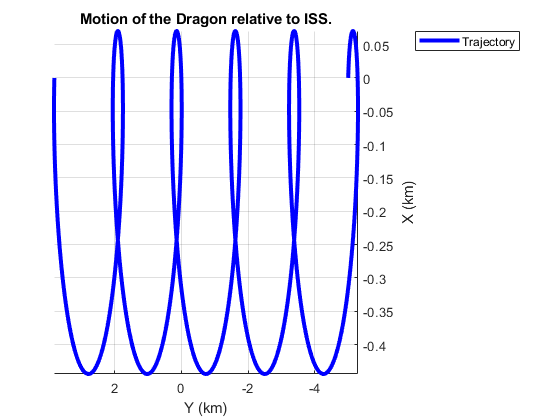

% Relative motion
n_orbits = 5;
t = linspace(0, n_orbits*2*pi/n, 1000);
delta_r = zeros(3, length(t)); 

for ii=1:length(t)
    [phi_rr, phi_rv, phi_vr, phi_vv] = CW_Matrices(n, t(ii));
    delta_r(:,ii) = phi_rr*dr0 + phi_rv*dv0_plus;
end

figure
plot3(delta_r(1,:), delta_r(2,:), delta_r(3,:), '-b', 'LineWidth',3);
xlabel('X (km)'); ylabel('Y (km)'); zlabel("Z (km)"); 
title('Motion of the Dragon relative to ISS.')
legend('Trajectory');
grid on; axis tight

## CR3BP

m1= 5.9742e24;               % Mass of earth (kgs)
m2= 7.347e22;               % Mass of moon (kgs)
pi1 = m1/(m1+m2);
pi2 = m2/(m1+m2);


r12 = 385748;

x1 = -pi2*r12;
x2 = pi1*r12;

r2 = x2 / 0.05;

r1 = -x1 / 0.05;

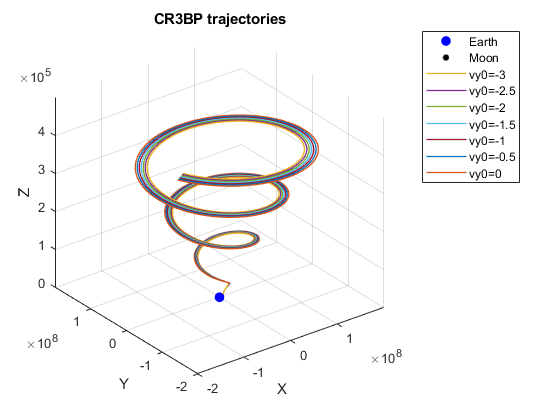

% A: initial conditions 1
x0 = 1.05*r2;
y0 = 0; 
z0 = 0;

vx0 = 0;
vz0 = 0.05;
vy_init = -3:0.5:0;
tspan = [0 100*24*60*60];

options = odeset('RelTol', 1.0e-5, 'AbsTol', 1.0e-5);

figure
plot3(x1,0,0,'.b','Markersize',25); 
hold on;
plot3(x2,0,0,'.k','Markersize',15); 

for ii=1:length(vy_init)
    
    vy0 = vy_init(ii); 
    INIT_y = [x0 y0 z0 vx0 vy0 vz0]';
    [t, y] = ode45(@CRTBP, tspan, INIT_y, options);
    plot3(y(:,1), y(:,2), y(:,3),'Linewidth', 1); 
    hold on; 
    
end

grid on; title('CR3BP trajectories');  hold off;
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('Earth','Moon','vy0=-3','vy0=-2.5', 'vy0=-2','vy0=-1.5','vy0=-1','vy0=-0.5','vy0=0')

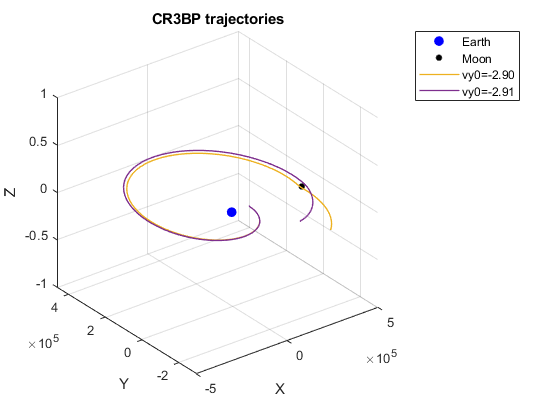

% B: initial conditions 2
x0 = 0.95*r1;
y0 = 0; 
z0 = 0;

vx0 = 0;
vz0 = 0.0;
vy_init = [-2.90, -2.91];
tspan = [0 14*24*60*60];

options = odeset('RelTol', 1.0e-5, 'AbsTol', 1.0e-5);

figure
plot3(x1,0,0,'.b','Markersize',25); 
hold on;
plot3(x2,0,0,'.k','Markersize',15); 

for ii=1:length(vy_init)
    
    vy0 = vy_init(ii); 
    INIT_y = [x0 y0 z0 vx0 vy0 vz0]';
    [t, y] = ode45(@CRTBP, tspan, INIT_y, options);
    plot3(y(:,1), y(:,2), y(:,3),'Linewidth', 1); 
    hold on; 
    
end

grid on; title('CR3BP trajectories');  hold off;
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('Earth','Moon','vy0=-2.90','vy0=-2.91')

## Functions

function ydot = CRTBP(~,y_)

% input

%  y(1) = x-component of position
%  y(2) = y-component of position
%  y(3) = z-component of position

%  y(4) = x-component of velocity
%  y(5) = y-component of velocity
%  y(6) = z-component of velocity

% output

%  ydot(1) = x component of velocity
%  ydot(2) = y component of velocity
%  ydot(3) = z component of velocity

%  ydot(4) = x component of acceleration
%  ydot(5) = y component of acceleration
%  ydot(6) = z component of acceleration


mu1 = 398600.44; mu2 = 4904.87;
omega = 2.662*1e-6; r12 = 385748;

m1= 5.9742E24;               % Mass of earth (kgs)
m2= 7.3459E22;               % Mass of moon (kgs)
pi1 = m1/(m1+m2);
pi2 = m2/(m1+m2);

 x = y_(1);
 y = y_(2);
 z = y_(3);
 vx = y_(4);
 vy = y_(5);
 vz = y_(6);

r1 = norm([ x+pi2*r12, y, z ]);
r2 = norm([ x-pi1*r12, y, z ]);


ax = 2*omega*vy + omega^2*x - ...
           ( mu1/r1^3 + mu2/r2^3 )*x - ...
           ( mu1*pi2/r1^3 - mu2*pi1/r2^3 ) * r12;

ay = -2*omega*vx + omega^2*y - ...
            ( mu1/r1^3 + mu2/r2^3 )*y;

az = -( mu1/r1^3 + mu2/r2^3 )*z;

ydot = [vx; vy; vz; ax; ay; az];

end

function [phi_rr, phi_rv, phi_vr, phi_vv] = CW_Matrices(n, t)

% Clohessy Wiltshire
phi_rr = [4-3*cos(n*t) 0 0; 
            6*(sin(n*t) - n*t) 1 0;
            0 0 cos(n*t)];

phi_rv = (1/n) * [sin(n*t)  2*(1-cos(n*t)) 0;
        2*(cos(n*t)-1)   4*sin(n*t)-3*n*t 0;
        0 0 sin(n*t)];

phi_vr = n* [3*sin(n*t) 0 0;
    6*(cos(n*t) - 1) 0 0;
    0 0 -sin(n*t)];

phi_vv = [cos(n*t) 2*sin(n*t) 0;
    -2*sin(n*t) 4*cos(n*t)-3 0;
    0 0 cos(n*t)]; 
    
end